首先运行MIL仿真程序然后再运行本实时脚本之后就能看到位置轨迹和高度.

该脚本对比了四旋翼在健康状态下和故障状态下的飞行轨迹,和飞行高度的不同. 此时飞机负载较小,动力充足.

结果表明在动力充足的情况下,单旋翼8.5N, 且质量为0.752kg, 单旋翼失效对整个系统的影响较小.

t = out.PosE.Time;
PosELength = out.PosE.Length;

PosEData = out.PosE.Data;
PosEDataX = PosEData(:,1);
PosEDataY = PosEData(:,2);
PosEDataZ = PosEData(:,3);
% 第一条线的颜色大小
PosEcolorR = linspace(1, 0, PosELength);
PosEcolorG = linspace(1, 1, PosELength);
PosEcolorB = linspace(0, 1, PosELength);
PosEcolor = [PosEcolorR; PosEcolorG; PosEcolorB];
% PosEcolor = 0:(1/(out.PosE.Length-1)):1;
colorMarker = PosEcolor;   % 颜色渐变
sizeMarker = linspace(20, 20, length(colorMarker));

%% 水平位置
PosEDataHealth = healthFlightData.PosE.Data;
PosEDataHealthX = PosEDataHealth(:,1);
PosEDataHealthY = PosEDataHealth(:,2);
PosEDataHealthZ = PosEDataHealth(:,3);
% 
% 第二条线的颜色大小
colorMarkerHealthR = linspace(0, 0, PosELength);   % 颜色单一
colorMarkerHealthG = linspace(0, 0, PosELength);
colorMarkerHealthB = linspace(0, 0, PosELength);
colorMarkerHealth = [colorMarkerHealthR; colorMarkerHealthG; colorMarkerHealthB];
sizeMarkerHealth = linspace(1, 1, length(colorMarker));

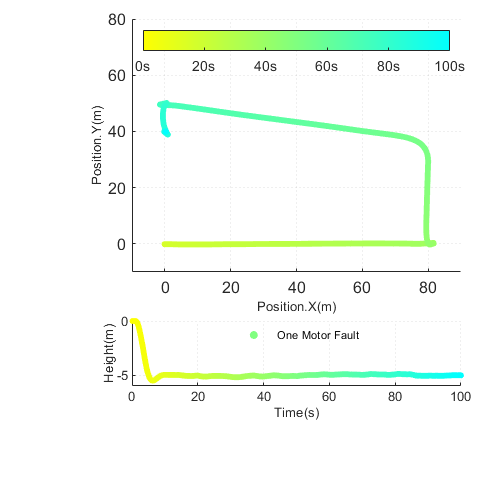

figure(1)
subplot(10,1,[1,2,3,4,5,6,7])
% scatter([PosEDataX;PosEDataHealthX], [PosEDataY;PosEDataHealthY], ...
%     [sizeMarker,sizeMarkerHealth], [colorMarker,colorMarkerHealth]','o', 'filled')
scatter(PosEDataX, PosEDataY, ...
    sizeMarker, colorMarker','o', 'filled')

ylim ([-10 80])
xlim ([-10 90])
xlabel('Position.X(m)','FontSize',10)
ylabel('Position.Y(m)','FontSize',10)
colormap(colorMarker');
colorbar( 'north','Ticks',[0, 0.2, 0.4,0.6, 0.8, 1],...
         'TickLabels',{'0s','20s','40s','60s','80s','100s'})

% 高度图
subplot(10,1,[9, 10])
% scatter([t;t], [PosEDataZ; PosEDataHealthZ], ...
%     [sizeMarker, sizeMarkerHealth], [colorMarker,colorMarkerHealth]','o', 'filled')
scatter(t, PosEDataZ, ...
    sizeMarker, colorMarker','o', 'filled')
 ylim ([-6 0])
% yticks([-6 -3 0 3])
% xticks([0 20 40 60 80 100])
ylabel('Height(m)','FontSize',10)
xlabel('Time(s)','FontSize',10)
legend('One Motor Fault','Location',"north")
legend('boxoff')

第二条线

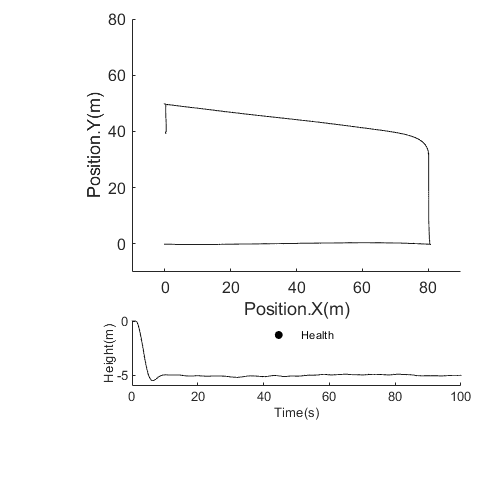

figure(2)
subplot(10,1,[1,2,3,4,5,6,7])
scatter(PosEDataHealthX, PosEDataHealthY, ...
    sizeMarkerHealth, colorMarkerHealth','o', 'filled')
ylim ([-10 80])
xlim ([-10 90])
xlabel('Position.X(m)','FontSize',10)
ylabel('Position.Y(m)','FontSize',10)


grid off
%% 高度
subplot(10,1,[9, 10])
% scatter([t;t], [PosEDataZ; PosEDataHealthZ], ...
%     [sizeMarker, sizeMarkerHealth], [colorMarker,colorMarkerHealth]','o', 'filled')
scatter(t, PosEDataHealthZ, ...
    sizeMarkerHealth, colorMarkerHealth','o', 'filled')
 ylim ([-6 0])
% yticks([-6 -3 0 3])
% xticks([0 20 40 60 80 100])
ylabel('Height(m)','FontSize',10)
xlabel('Time(s)','FontSize',10)
legend('Health','Location',"north")
legend('boxoff')
grid off

% x = 0 : 0.1 : 2*pi;
% y = sin(x);
% sizeMarker = linspace(1, 100, length(x));    % 比0大，值越大标记越大
% colorMarker = y;   % 颜色渐变
% subplot(1,2,1)
% scatter(x, y, sizeMarker, colorMarker, 'o', 'filled')
% subplot(1,2,2)
% patch([x NaN],[y NaN],[colorMarker NaN],'Marker','o','EdgeColor','interp','MarkerFaceColor','flat')